# 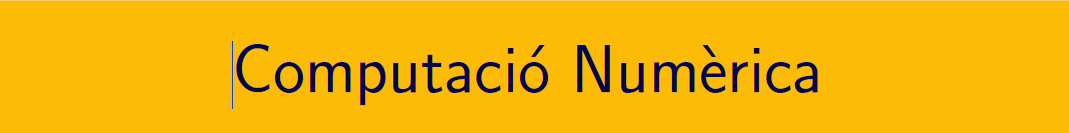

================================================================================

# Pràctica 11. Integració aproximada de funcions i dades.

`Document preparat per M. Àngela Grau Gotés - 12 de maig de 2022`

## Introducció

Exercicis del document MN_full9.pdf, el podeu trobar en el campus virtual. 

En la pràctica 10 de dimecres 5 de maig de 2022 vàrem treballar les fórmules d'integració simples i compostes 

- del punt mig (o rectangle)

- dels trapezis

- de Simpson

- romberg

## 1 RECORDEM .....

Obteniu una expressió analítica per a $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\$

syms z f(z)
f(z) = exp(-z^2/2)
ve = int(f(z),-1,1)

### Exercici 1. Fórmules de Newton-Côtes compostes. Mètode Romberg.

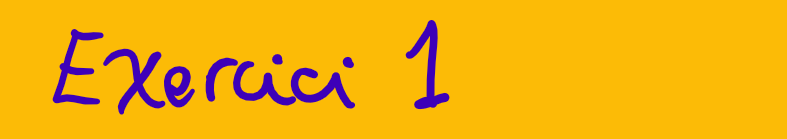

Bajarse el código de [romberg.m](http://www.math.mcgill.ca/gantumur/math578f09/matlab/romberg.m)

            
$$\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$$


- Valor exacte

clearvars;
format shortG

%vea = integral(@(x)exp(-x.^2./2),-1,1,'RelTol',0,'AbsTol',0.510^(-14))
%cebada

a = -1; b = 1; 
f = @(x) exp(-x.^2/2);
I = integral(f,a,b) %sqrt(2*pi)*erf(sqrt(2)/2) 

- Mètode del punt mig, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que P(h), P(h/2) ...  millora l'aproximació

% my_midp(f,a,b,0:6)
for k = 0:6
    n(k+1) = 2^k;   % intervals
    P(k+1) = midp(f,a,b,n(k+1));
end
disp(array2table([n; (b-a)./n; P; abs(P-I)]','VariableNames',{'n','h','Rectangle','error absolut'}))

- Mètode dels trapezis, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que T(h), T(h/2) ...  millora l'aproximació

for k = 0:6
    n(k+1) = 2^k;
    T(k+1) = trap(f,a,b,n(k+1));
end
disp(array2table([n; (b-a)./n; T; abs(T-I)]','VariableNames',{'n','h','Trapezis','error absolut'}))

- Regla de Simpson, h=1,1/2,1/4,1/8. Exercici per verificar que S(h), S(h/2) ...  millora l'aproximació

for k = 0:6
    n(k+1) = 2^k;
    S(k+1) = simp(f,a,b,n(k+1));
end
disp(array2table([n; (b-a)./n; S; abs(S-I)]','VariableNames',{'n','h','Simpson','error absolut'}))

- Mètode de Romberg, h=1,1/2,1/4,1/8,1/16

r=romberg(@exp,0,1,5)     %%matriu representan la taula d'extrapolació

[R,h] = romberg(f,a,b,4);
[h',R]
[h',tril(abs(R-I))]
[h',tril(fix(-log10(2*abs(R-I))))]

### Exercici 2. Mètode de Montecarlo

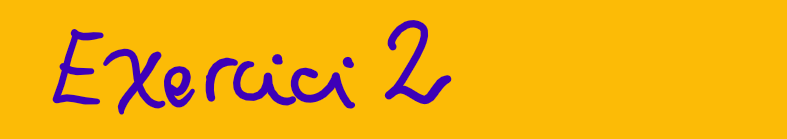

Calculeu el valor de    $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$ 

- Tipus I (valor esperat)

%la vella confiable
g = @(x)exp(-x.^2/2)
M = 10^6; %100000000
a = -1; 
b = 1;
x = a+ (b-a)*rand(M,1);
IM = (b-a)/M*sum(g(x))
ordre = 1/sqrt(M)   
dc = abs(IM-1.71124878378430)

%la novetat
g = @(x)(exp(-x.^2/2));
for k=1:5
    M(k) = 10^k;
    x = a+(b-a)*rand(M(k),1);
    y = g(x);
    va(k) = (b-a)/M(k)*sum(y);
end
[1:k;M; va; abs(va-I)]'
montecarloFuncio(g,a,b,1:5);

- Tipus II (hit or miss)

%la que funciona
k=0;
m=1000000;
P =zeros(m,2);
for n=1:m
    x = rand;
    y = rand;
    if y <= g(x) 
        k = k+1;
        P(n,:) = [x;y];
    end
end

valor_aprox = (b-a)*k/m %quants dels tests que hem fes estan dins l'area

dc= abs(valor_aprox - IM)
t = a:0.05:b; yt = f(t);
plot(P(:,1),P(:,2),'.',t,yt,'r','LineWidth',2)

%la casi bona
fplot(g,[-1,1],'Color','r','LineWidth',2)
axis([-1,1,0,1])
hold on
a = -1; b = 1;
M = 100000;
x = a + (b-a)*rand(M,1);
y = rand(M,1);   % entre 0 a 1 mirant gràfica
v = y <= g(x);
V = sum(v);
valor_aproximat = V/M*(b-a)
aprox = abs(I-valor_aproximat)
plot(x(v),y(v),'b.'), hold off

%el mètode
montecarloHitMiss(g,a,b,100000)

## 2 APRENEM .....

### Fórmules d'integració GAUSSIANA

Podeu descarregar els codis de MatLab File Exchange:   

- [Gaussian quadratures for several orthogonal polynomials](https://es.mathworks.com/matlabcentral/fileexchange/48144-gaussian-quadratures-for-several-orthogonal-polynomials) (Chebyshev)

- [Legendre Laguerre and Hermite - Gauss Quadrature](https://es.mathworks.com/matlabcentral/fileexchange/26737-legendre-laguerre-and-hermite-gauss-quadrature?s_tid=prof_contriblnk)

### Polinomis de Legendre

clc,clearvars
m = 3;
[xi, w, P] = gauss_quad(m,'legen')  % Felipe Uribe, Gaussian quadratures for several orthogonal polynomials 

### Polinomis de Chebyshev

clc,clearvars
m = 3;
[xi,w,P] = gauss_quad(m,'cheby')

### Polinomis de Laguerre

clc,clearvars
m = 3;
[xi,w,P] = gauss_quad(m,'lague')

### Polinomis de Hermitte

clc,clf,clearvars
m = 3;
[xi,w,P] = gauss_quad(m,'he_phys')

### Exercici 3. Gauss-Legendre

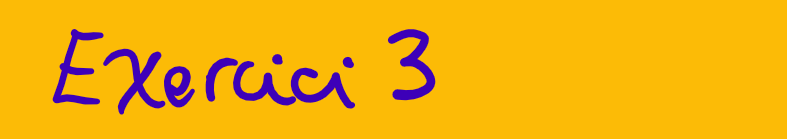

Calcular $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$

- Valor exacte

clearvars
valorIntegral = integral(@(x)exp(-x.^2/2),-1,1);   % valor exacte
fprintf('integral valor numèric exacte = %0.14f\t',valorIntegral);

- Fórmula de dos punts: m=2

format longG
% Gauss Legendre 
f = @(x)exp(-x.^2/2);
a = -1; 
b = 1;
%%
m = 2
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))
Gerror = abs(GL2-valorIntegral)

- Fórmula de tres punts: m=3

format longG
% Gauss Legendre 
f = @(x)exp(-x.^2/2);
a = -1;
b = 1;
%%
m = 3
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))
Gerror = abs(GL2-valorIntegral)

- Fórmula de quatre punts: m=4

format longG
% Gauss Legendre 
f = @(x)exp(-x.^2/2);
a = -1; 
b = 1;
%%
m = 4
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))
Gerror = abs(GL2-valorIntegral)

- Fórmula de cinc punts: m=5

format longG
% Gauss Legendre 
f = @(x)exp(-x.^2/2);
a = -1; 
b = 1;
%%
m = 5
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))
Gerror = abs(GL2-valorIntegral)

### Exercici 4. Gauss-Chebyshev

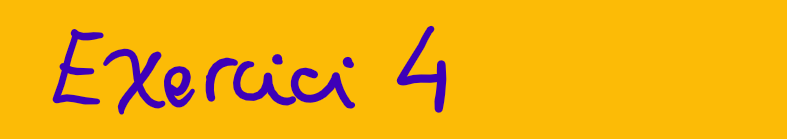

Calculeu el valor de    $$\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$ 

- Valor exacte

clc; clear variables; format compact;
format longG;
a=-1;b=1;
f = @(x)cos(pi*x)./sqrt(1-x.^2)
integral(f, a, b)

- Fórmula de dos punts: m=2. Compareu el valor calculat per trapezis (1interval=dos punts)

m = 2
[x, w] = gauss_quad(m,'cheby');
GL2 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL2-valorIntegral)

- Fórmula de tres punts: m=3.  Compareu el valor calculat per Simpson (1interval=tres punts)

m = 3
[x, w] = gauss_quad(m,'cheby');
GL2 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL2-valorIntegral)

- Fórmula de quatre punts: m=4

m = 4
[x, w] = gauss_quad(m,'cheby');
GL2 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL2-valorIntegral)

- Fórmula de cinc punts: m=5

m = 5
[x, w] = gauss_quad(m,'cheby');
GL2 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL2-valorIntegral)

### Exercici 5. Canvi interval

## 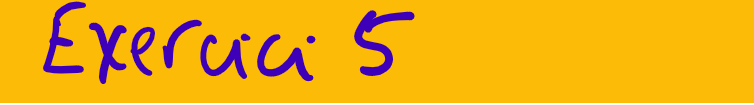

 Calculeu el valor de $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx $ fent ús de fórmules de Gauss-Legendre. Obseveu que el canvi d'interval és $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx = \frac{1}{2}\int_{-1}^{1} \ln\Big(\frac{t+3}{2}\Big)\,dt \,.$

f  = @(x)log(x);
a  = 1; b = 2;
valorIntegral = integral(f,a,b);   % valor exacte
fprintf('integral valor numèric exacte = %0.14f\t',valorIntegral);
%%
m = 4
[x, w] = GaussLegendre_2(m)
GL4    = 0.5*sum(w.*f((x+3)/2))
Gerror = abs(GL4-valorIntegral)

## 3 PRACTIQUEM ....

### Pràctica 26. Integració gaussiana de dos punts.

Fent ús d'una fórmula d'integració gaussiana de dos punts calculeu:

- 
$$$ \rm{a)}\quad\displaystyle\int_{-1}^{1}e^xdx $$$
 

f  = @(x)exp(x)
a  = -1; b = 1;
valorIntegral = integral(f,a,b);   % valor exacte
fprintf('integral valor numèric exacte = %0.14f\t',valorIntegral);

%Gauss-Legendre m = 2
m = 2
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))

%Error
Gerror = abs(GL2-valorIntegral)

- 
$$$\rm{b)}\quad\displaystyle \int_{0}^{1}(7+14x^6)dx $$$


f  = @(x)(7+14*x.^6)
a  = 0; b = 1;
valorIntegral = integral(f,a,b);   % valor exacte
fprintf('integral valor numèric exacte = %0.14f\t',valorIntegral);

%Gauss-Legendre m = 2
m = 2
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))

%Error
Gerror = abs(GL2-valorIntegral)

- 
$$$\rm{c)}\quad\displaystyle \int_{0}^{3}x^2e^{x} dx $$$


% f  = @(x)x.^2*exp(x)
% a  = 0; b = 3;
% valorIntegral = integral(f,a,b);   % valor exacte
% fprintf('integral valor numèric exacte = %0.14f\t',valorIntegral);
% 
% %Gauss-Legendre m = 2
% m = 2
% [x, w] = GaussLegendre_2(m);
% GL2    = sum(w.*f(x))
% 
% %Error
% Gerror = abs(GL2-valorIntegral)

### Pràctica 26. Integració gaussiana de quatre punts.

Fent ús d'una fórmula d'integració gaussiana de quatre punts calculeu:

- 
$$$\rm{a)}\quad\displaystyle \int_{-1}^{1}cos(x) dx $$$


format longG
% Gauss Legendre 
f = @(x)cos(x);
a = -1; 
b = 1;
valorIntegral = integral(f,a,b)

m = 4
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))
Gerror = abs(GL2-valorIntegral)

- 
$$$\rm{b)}\quad\displaystyle \int_{-1}^{1}e^xdx $$$


format longG
% Gauss Legendre 
f = @(x)exp(x)
a = -1; 
b = 1;
valorIntegral = integral(f,a,b)

m = 4
[x, w] = GaussLegendre_2(m);
GL2    = sum(w.*f(x))
Gerror = abs(GL2-valorIntegral)

- $$\rm{c)}\quad\displaystyle \int_{0}^{1}\ln(x)sin^2(x)dx $$  (Canvi d'interval)

%no se cambiar d'interval aqui

- $$\rm{d)}\quad\displaystyle \int_{0}^{1}\ln(1+\cos(x))dx $$  (Canvi d'interval)

%no se cambiar d'interval aqui

### Pràctica 26. Integració per Gauss-Chebyschev.

Calculeu les integrals següents per Gauss-Txebisxev, per m=2, 3, 4 i 5 punts


$$$\rm{a)}\quad\displaystyle  \int_{-1}^{1}\frac{x^2}{\sqrt{1-x^2}}dx $$$


clc,clf,clearvars

a = -1;
b = 1;
f = @(x)(x.^2)./(sqrt(1-x.^2))
integral(f, a, b)
m = 2

[x,w,P] = gauss_quad(m,'cheby')
GL2 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL2-valorIntegral)

m = 3

[x,w,P] = gauss_quad(m,'cheby')
GL3 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL3-valorIntegral)

m = 4

[x,w,P] = gauss_quad(m,'cheby')
GL4 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL4-valorIntegral)

m = 5

[x,w,P] = gauss_quad(m,'cheby')
GL5 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL5-valorIntegral)


$$$\rm{b)}\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$$


clc,clf,clearvars

a = -1;
b = 1;
f = @(x)cos(pi*x)./sqrt(1-x.^2)
integral(f, a, b)
m = 2

[x,w,P] = gauss_quad(m,'cheby')
GL2 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL2-valorIntegral)

m = 3

[x,w,P] = gauss_quad(m,'cheby')
GL3 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL3-valorIntegral)

m = 4

[x,w,P] = gauss_quad(m,'cheby')
GL4 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL4-valorIntegral)

m = 5

[x,w,P] = gauss_quad(m,'cheby')
GL5 = sum(w.*f(x))
valorIntegral = integral(f,a,b)   % valor exacte
Gerror=abs(GL5-valorIntegral)

$$\rm{c)}\quad\displaystyle  \int_{0}^{1}\frac{x^2}{\sqrt{x(1-x)}}dx $$ (Canvi d'interval)

function r = trap(f,a,b,n)
h = (b - a) / n;
r = f(a) * 0.5;
x = a + h;
for i = 1 : n-1
    r = r + f(x);
    x = x + h;
end;
r = r + f(b) * 0.5;
r = r * h;
end
% % % Códigos de matlab file exchange y de códigos math 578
%
% % http://www.math.mcgill.ca/gantumur/math578f09/matlab/romberg.m
% function r = romberg(f,a,b,n)
% h = (b - a) ./ (2.^(0:n-1));
% r(1,1) = (b - a) * (f(a) + f(b)) / 2;
%     for j = 2:n
%         subtotal = 0;
%         for i = 1:2^(j-2)
%             subtotal = subtotal + f(a + (2 * i - 1) * h(j));
%         end
%         r(j,1) = r(j-1,1) / 2 + h(j) * subtotal;
%         for k = 2:j
%             r(j,k) = (4^(k-1) * r(j,k-1) - r(j-1,k-1)) / (4^(k-1) - 1);
%         end
%     end
% return
% end
%----------------------
function r = simp(f,a,b,n)
h = (b - a) / (n * 2);
r = f(a);
x = a + h;
for i = 1 : n-1
    r = r + 4 * f(x);
    x = x + h;
    r = r + 2 * f(x);
    x = x + h;
end;
r = r + 4 * f(x);
r = r + f(b);
r = r * h/3;
return
end

function [xi,w,P] = gauss_quad(m,type)
    %{
    Comments:
    input:   m     - quadrature points
             type  - chosen orthogonal polynomial weighting function:
                     'he_prob': Hermite probabilist
                     'he_phys': Hermite physicist
                     'legen'  : Legendre
                     'cheby'  : Chebyshev
                     'lague'  : Laguerre
    output:  xi - orthogonal polynomial roots
             w  - weights
    %}
    syms x;
    switch type
       case 'he_prob'
          P    = cell(m+1,1);
          P{1} = 1;
          P{2} = [1 0]; 
          for n = 2:m
             P{n+1} = [P{n} 0] - (n-1)*[0 0 P{n-1}];
          end
          w_x = exp(-x^2/2)/sqrt(2*pi);
          a = -Inf;   b = Inf;
          
       case 'he_phys'
          P    = cell(m+1,1);
          P{1} = 1;      
          P{2} = [2 0];  
          for n = 2:m
             P{n+1} = 2*[P{n} 0] - (2*(n-1))*[0 0 P{n-1}];  
          end
          w_x = exp(-x^2);
          a = -Inf;   b = Inf;
          
       case 'legen'  
          P    = cell(m+1,1);
          P{1} = 1;      
          P{2} = [1 0];  
          for n = 2:m
             P{n+1} = ((2*n-1)*[P{n} 0] - (n-1)*[0 0 P{n-1}])/n; 
          end
          w_x = 1;
          a = -1;   b = 1;
          
       case 'cheby'
          P    = cell(m+1,1);
          P{1} = 1;
          P{2} = [1 0];
          for n = 2:m
             P{n+1} = 2*[P{n} 0] - [0 0 P{n-1}]; 
          end
          w_x = 1/sqrt(1-x^2);
          a = -1;   b = 1;
       case 'lague'
          P     = cell(m+1,1);
          alpha = 0;           
          P{1}  = 1;           
          P{2}  = [-1 1+alpha];
          for n = 2:m
             P{n+1} = (((2*n-1+alpha)*[0 P{n}]-[P{n} 0]) - (n-1+alpha)*[0 0 P{n-1}])/n; 
          end
          w_x   = (x^alpha)*exp(-x);
          a = 0;   b = Inf;
          
       otherwise
          error('You must choose between "he_prob", "he_phys", "legen", "cheby", "lague"');
    end
    xi = sort(roots(P{m+1}));
    w  = zeros(m,1);
    id = eye(m);
    warning('off','all'); 
    for i = 1:m
       lag_pol = poly2sym(polyfit(xi,id(:,i),m-1),x); 
       w(i)    = int(lag_pol*w_x, x, a, b);
    end  
    if ~isreal(w)
       error('m is too large. The weights cannot be complex.');
    end
    close all;
    figure;
    plot(xi,w,'bo','LineWidth',2); 
    set(gca,'FontSize',12);
    grid minor; axis tight; ylim([min(w)-0.1 max(w)+0.1]);
    xlabel('Zeros','FontSize',12);
    ylabel('Weights','FontSize',12);
    xx = min(xi):0.01:max(xi);
    yy = zeros(m,length(xx));
    figure;
    for i = 1:m
       yy(i,:) = polyval(P{i},xx);
    end
    h = plot(xx,yy,'LineWidth',2);
    legend(h,'Location','Best'); 
    set(gca,'FontSize',12);
    grid minor; axis tight; 
    xlabel('x','FontSize',12);
    ylabel('P_n(x)','FontSize',12);
    return;
end

function [x, w] = GaussHermite_2(n)
    i       = 1:n-1;
    a       = sqrt(i/2);
    CM      = diag(a,1) + diag(a,-1);
    [V L]   = eig(CM);
    [x ind] = sort(diag(L));
    V       = V(:,ind)';
    w       = sqrt(pi) * V(:,1).^2;
end

function [x, w] = GaussLaguerre_2(n, alpha)
    i       = 1:n;
    a       = (2*i-1) + alpha;
    b       = sqrt( i(1:n-1) .* ((1:n-1) + alpha) );
    CM      = diag(a) + diag(b,1) + diag(b,-1);
    [V L]   = eig(CM);
    [x ind] = sort(diag(L));
    V       = V(:,ind)';
    w       = gamma(alpha+1) .* V(:,1).^2;
end

function [x, w] = GaussLegendre_2(n)
    i       = 1:n-1;
    a       = i./sqrt(4*i.^2-1);
    CM      = diag(a,1) + diag(a,-1);
    [V L]   = eig(CM);
    [x ind] = sort(diag(L));
    V       = V(:,ind)';
    w       = 2 * V(:,1).^2;
end


% function r = romberg(f,a,b,n)
% h = (b - a) ./ (2.^(0:n-1));
% r(1,1) = (b - a) * (f(a) + f(b)) / 2;
% for j = 2:n
%     subtotal = 0;
%     for i = 1:2^(j-2)
%         subtotal = subtotal + f(a + (2 * i - 1) * h(j));
%     end
%     r(j,1) = r(j-1,1) / 2 + h(j) * subtotal;
%     for k = 2:j
%         r(j,k) = (4^(k-1) * r(j,k-1) - r(j-1,k-1)) / (4^(k-1) - 1);
%     end
% end
% end
function [r,h] = romberg(f,a,b,n)
h = (b - a) ./ (2.^(0:n-1));
r(1,1) = (b - a) * (f(a) + f(b)) / 2;
for j = 2:n
    subtotal = 0;
    for i = 1:2^(j-2)
        subtotal = subtotal + f(a + (2 * i - 1) * h(j));
    end
    r(j,1) = r(j-1,1) / 2 + h(j) * subtotal;
    for k = 2:j
        r(j,k) = (4^(k-1) * r(j,k-1) - r(j-1,k-1)) / (4^(k-1) - 1);
    end
end
end


function r = midp(f,a,b,n)
h = (b - a) / n;
x = a + h * 0.5;
r = 0;
for i=1:n
    r = r + f(x);
    x = x + h;
end
r = r * h;
end

%cagum la merda aquesta 
function [x, w] = GaussTxebixev_2(n)
    w = pi/n.*ones(1,n);
    k = 1:n;
    x = cos((2.*k-1).*pi./(2*n));
end

%montecarlo
function valor = montecarloFuncio(f,a,b,k)
    n = length(k); TM = [];
    ve = integral(f,a,b);
    for i = 1:n
        m = 10^k(i);
        x = a+(b-a)*rand(m,1);
        valor = (b-a)*sum(f(x))/m;
        TM = [TM; k(i), m, valor, abs(valor-ve), fix(-log10(2*abs(valor-ve)))];
    end
    taula = array2table(TM,'VariableNames',{'k','M','f(_)','error', 'xifres'});
    disp(taula)
end

%monecarlo hitMiss
function valor = montecarloHitMiss(f,a,b,m)
    x = (b-a).*rand(m,1) + a;
    y = (b-a).*rand(m,1) + a;
    k = 0;
    for i = 1:m
        if f(x(i),y(i)) <= 1
            k = k+1;
        end
    end
    valor = (b-a)*2*k/m;
end